Flint Morgan HW 4

- Kernel Ridge Regression

a)

rand('state',0);
randn('state',0);
lambda = 0.000000000001

lambda = 1.0000e-12

n = 100;
x = rand(n,1); % training inputs
y = sin(9*x) + sqrt(1/3)*randn(n,1); % training outputs
t = linspace(0,1,1001); % test inputs
k = (x*t+1).^4;
K = (x*x'+1).^4;
f = y'*inv(K+lambda*eye(n))*k;

mse = norm(f-sin(9*t))^2/n

mse = 0.2318

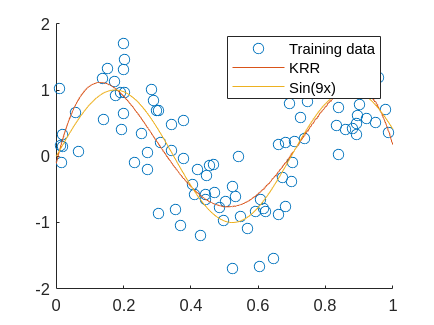


figure
hold on
scatter(x,y)
plot(t,f)
plot(t,sin(9*t))
legend(["Training data" "KRR" "Sin(9x)"])

b)

min_mse = 1000;
for lambda = 0.01:0.001:0.05

    for bandwidth = 0.001:0.001:0.1
        k = exp(-((x*t).^2)/(2*bandwidth^2));
        K = exp(-((x*x').^2)/(2*bandwidth^2));
        f = y'*inv(K+lambda*eye(n))*k;
    
    
        mse = norm(f-sin(9*t))^2/n;
        if mse < min_mse
            min_mse = mse;
            min_band = bandwidth;
            min_f = f;
            min_lambda = lambda;
        end
    end
end
min_mse

min_mse = 0.1479

min_band

min_band = 0.1000

min_lambda

min_lambda = 0.0500

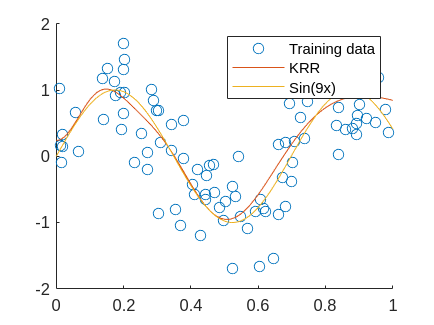

figure
hold on
scatter(x,y)
plot(t,f)
plot(t,sin(9*t))
legend(["Training data" "KRR" "Sin(9x)"])

2. SVM

a)

clear;
load('/home/flint/Desktop/2023-Fall/machine learning independent study/Hw04/hw04_files/mnist_49_3000.mat');
train_x = x(:,1:2000);
train_y = y(1,1:2000);
test_x = x(:,2001:end);
test_y = y(:,2001:end);
min_error= 1000;

p = 1;
k = (train_x(:,1:1000)'*train_x(:,1:1000)+1).^p;
for C = logspace(-4,4,50)
    
    [alpha,bias] = smo(k,train_y(:,1:1000),C,0.001);
    kval = (train_x(:,1001:2000)'*train_x(:,1:1000)+1).^p;
    f = sign((alpha.*train_y(:,1001:2000))*kval+bias);
    error = sum(f~=train_y(:,1001:2000))/1000;
    if error < min_error
        min_error = error;
        min_C = C;
        min_aplha = alpha;
        min_bias = bias;
    end
end
k = (test_x'*train_x(:,1:1000)+1).^p;
f = sign((min_aplha.*test_y)*k+min_bias);
min_error

min_error = 0.4710

error = sum(f~=test_y)/1000

error = 0.4920

b)

%imagesc(reshape(x(1,:),28,28)')
%colormap(gray)
%axis square
%axis off
%if y(1) == -1
%title('4')
%else
%title('9')
%end